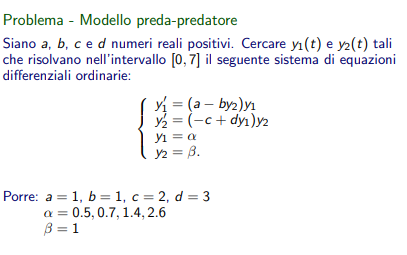

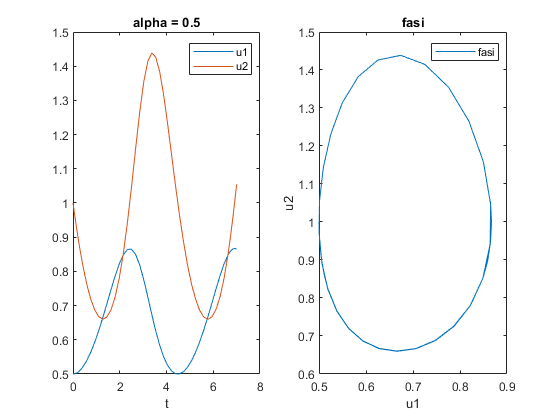

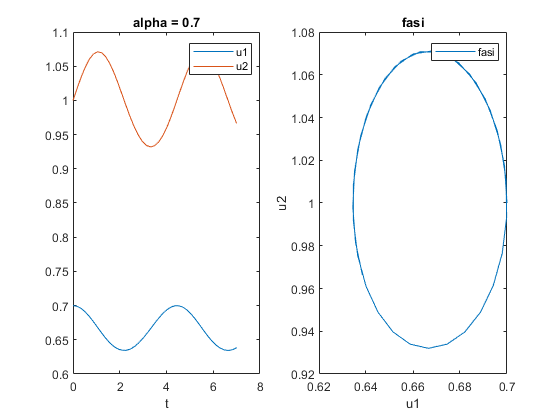

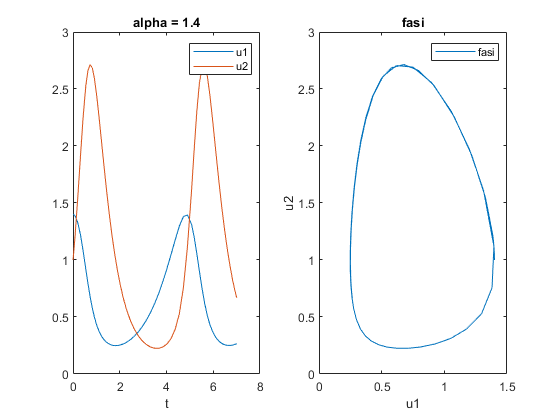

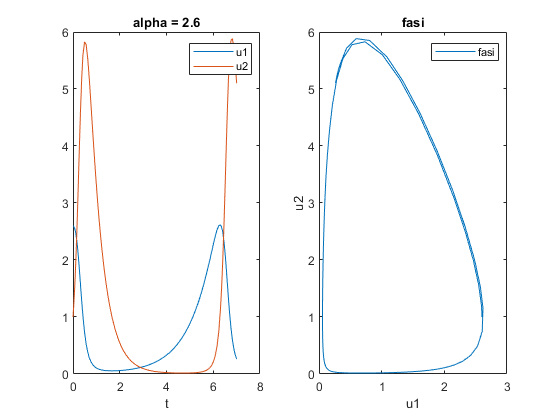

clear all
close all
opt=odeset("RelTol",1e-6);
a=1; 
b=1;
c=2;
d=3;
beta=1;
% f matrice definata come vettore dell'equazioni differenziali
% y punti di partenza celle soluzion in orfine come f
for alpha = [0.5,0.7,1.4,2.6]
    f=@(t,y) [(a-b.*y(2)).*y(1);(-c+d.*y(1)).*y(2)];
    y=[alpha beta];
    options=odeset('OutputFcn','odephas2');
    [t,u] = ode45(f,[0 7],[alpha;beta]);
    figure()
    subplot(1,2,1)
    plot(t,u)
    title("alpha = "+alpha)
    legend("u1","u2")
    xlabel t
    subplot(1,2,2)
    plot(u(:,1),u(:,2))
    title("fasi")
    legend("fasi")
    xlabel u1
    ylabel u2
end

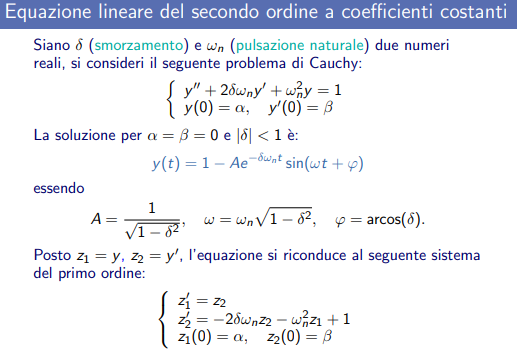

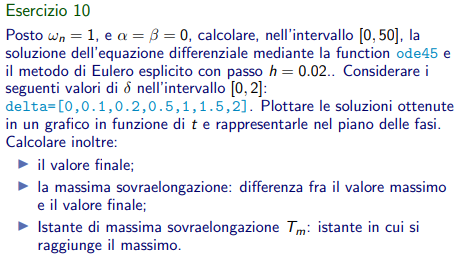

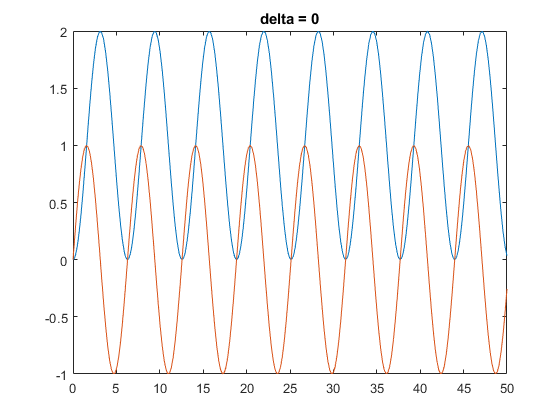

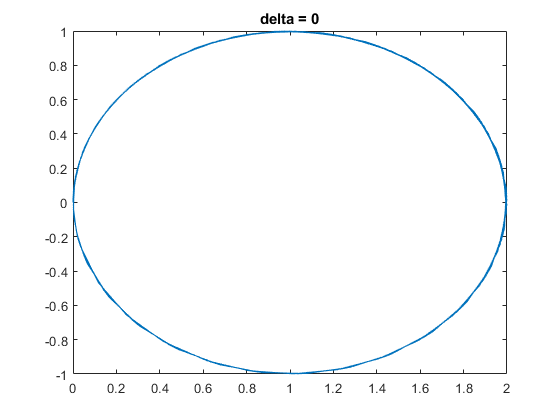

tempo = 34.5361


S = 1.9649

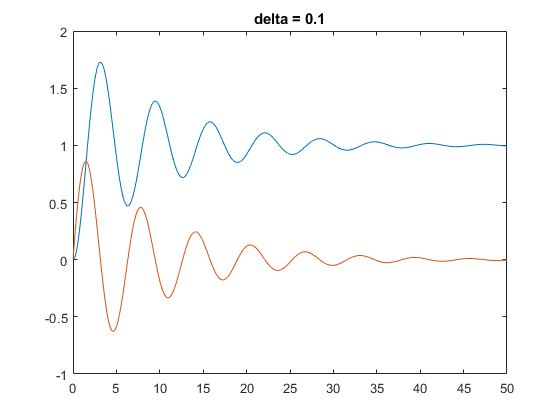

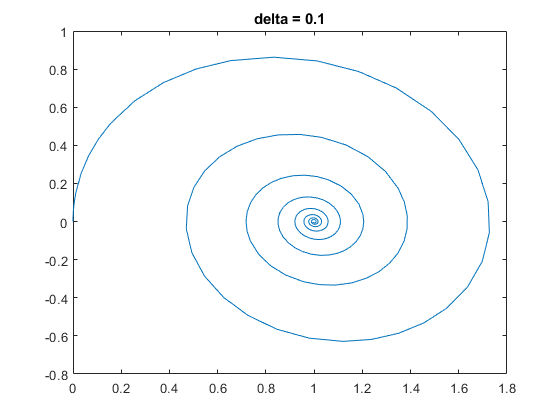

tempo = 3.2356


S = 0.7324

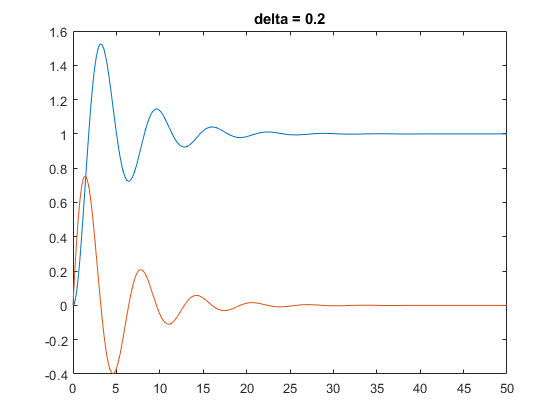

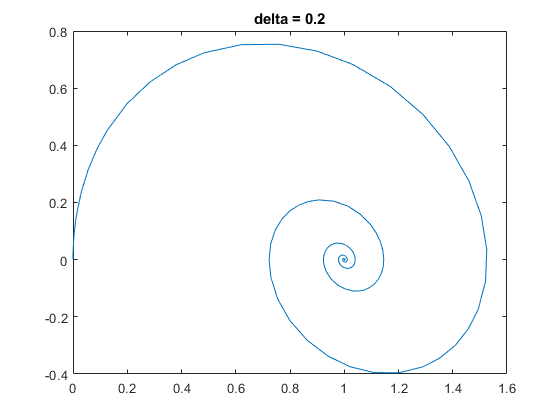

tempo = 3.1406


S = 0.5254

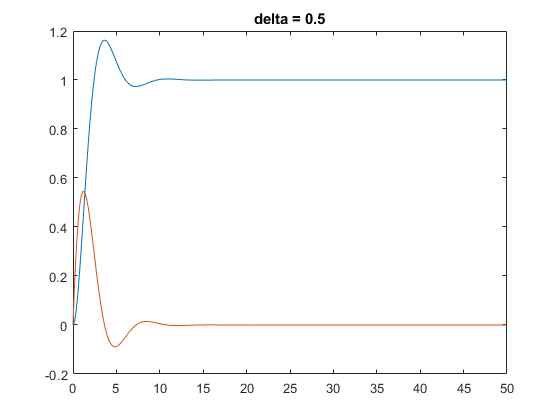

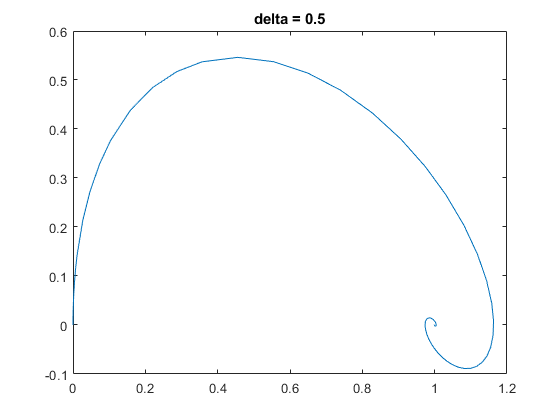

tempo = 3.5792


S = 0.1628

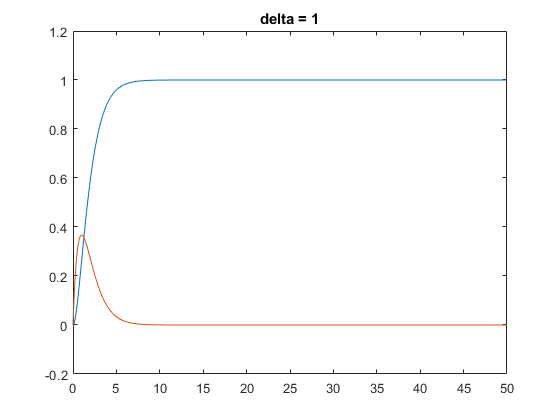

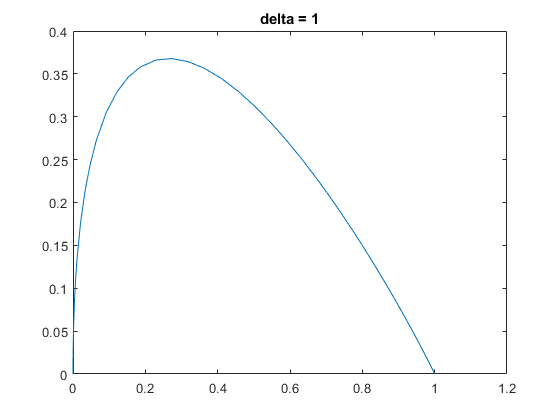

tempo = 45.4054


S = 5.9713e-07

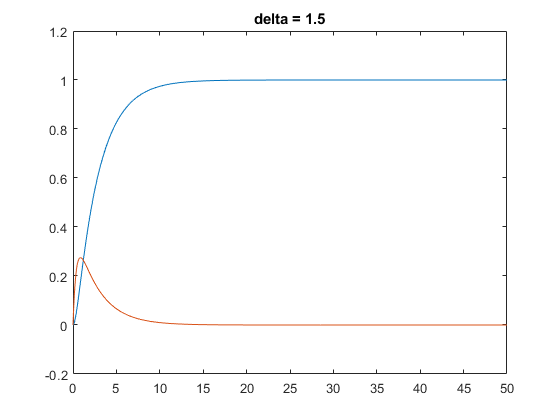

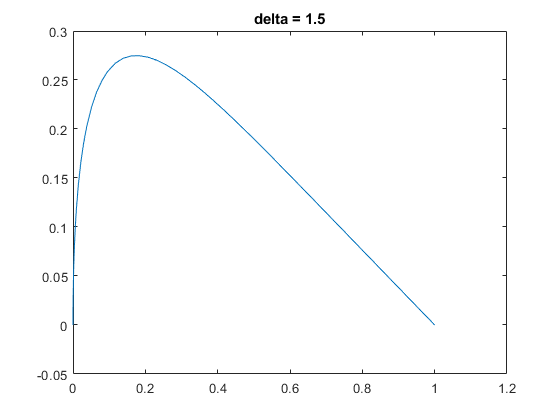

tempo = 49.5975


S = 2.4340e-07

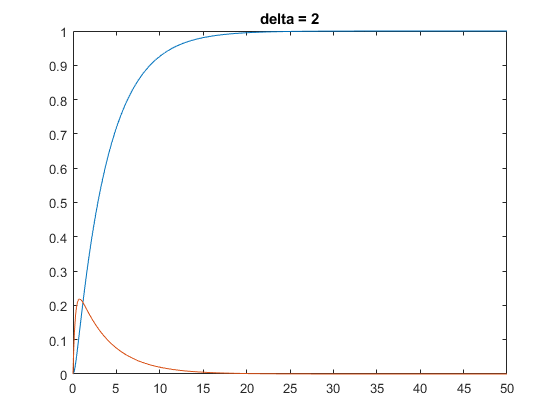

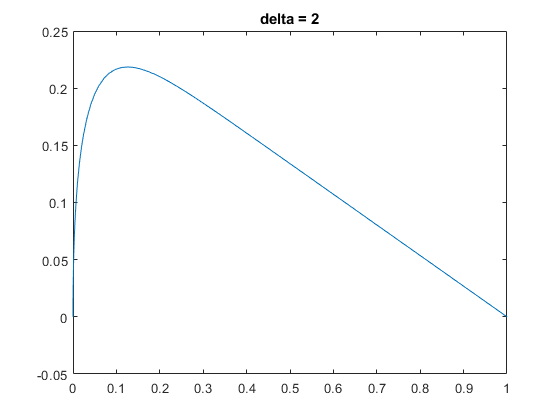

tempo = 50


S = 0

clear all
close all
alpha = 0; beta = 0;
wn = 1;
y =[alpha; beta];
deltas = [0 0.1 0.2 0.5 1 1.5 2];
Vf  = zeros(1,length(deltas));
for i = 1:1:length(deltas)
    
    f = @(t,y) [y(2) ; -2*deltas(i)*wn.*y(2)-wn^2.*y(1)+1];
    
    [t,u] = ode45(f,[0 50],y);
    figure
    plot(t,u(:,1),t,u(:,2))
    title("delta = "+deltas(i))
    figure
    plot(u(:,1),u(:,2))
    title("delta = "+deltas(i))
    Vf(i) = u(end,1);
    [SM ,TM] = max(u(:,1));
    disp("tempo = " +t(TM))
    S = SM-u(end,1)
end

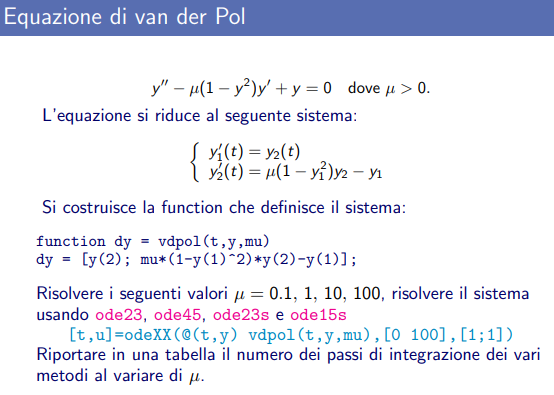

clear all
close all
mu_ = [0.1 1 10 100]

mu_ =     0.1000    1.0000   10.0000  100.0000


ode_23=zeros(1,length(mu_));    
ode_45=zeros(1,length(mu_));      
ode_23s=zeros(1,length(mu_));      
ode_15s=zeros(1,length(mu_));

for i = 1:1:length(mu_)
      mu = mu_(i);
      yp= @(t,y) [y(2); mu*(1-y(1).^2).*y(2)-y(1)];
      [t,u]=ode23(yp,[0 100],[1;1]);
      ode_23(i)=length(u);
      [t,u]=ode45(yp,[0 100],[1;1]);
      ode_45(i)=length(u);
      [t,u]=ode23s(yp,[0 100],[1;1]);
      ode_23s(i)=length(u);
      [t,u]=ode15s(yp,[0 100],[1;1]);
      ode_15s(i)=length(u);
end
T = table(mu_',ode_15s',ode_23s',ode_45',ode_23')

T = 4×5 table
    Var1    Var2    Var3    Var4     Var5
    ____    ____    ____    _____    ____
    0.1      586     614      509     471
      1      975     838     1065     775
     10     1077    1005     2813    1220
    100      305     299    23473    7835

The VariableNames property must contain one name for each variable in the table.

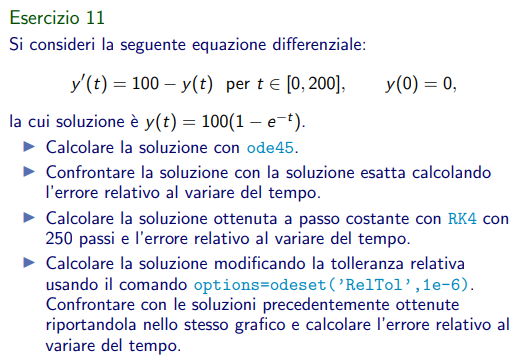

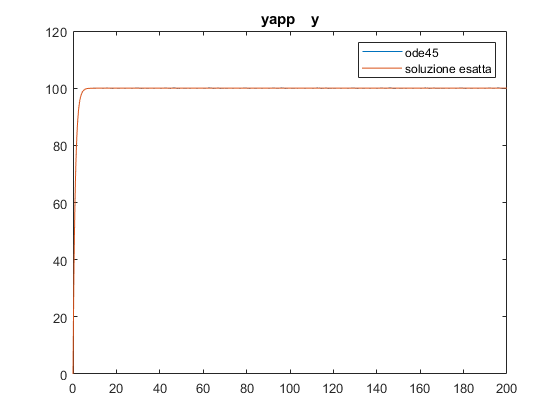

clear all
close all

f = @(t,y) 100-y;
ys = @(t) 100*(1-exp(-t));
[t,u]=ode45(f,[0 200],0);
plot(t,u)
hold on
fplot(ys,[0 200])
legend('ode45',"soluzione esatta")
title("yapp    y")

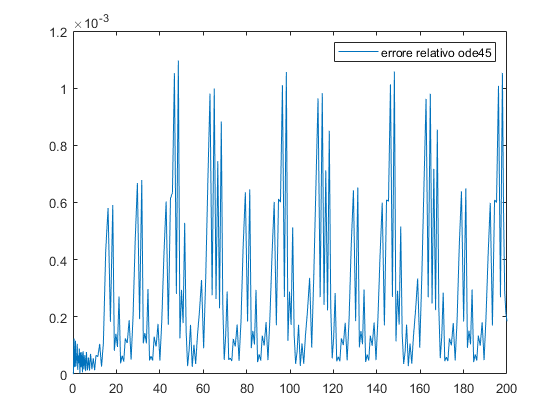

figure
err = abs((ys(t)-u)./(ys(t)));
plot(t,err)

legend("errore relativo ode45")

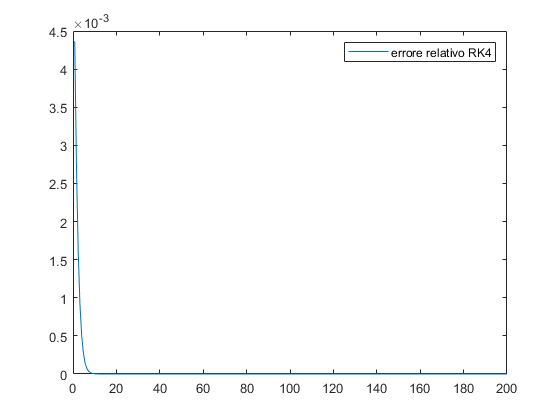

[tu,uu]=RK4(f,0,200,0,250);
figure
err = abs((ys(tu)-uu)./(ys(tu)));
plot(tu,err)
legend("errore relativo RK4")

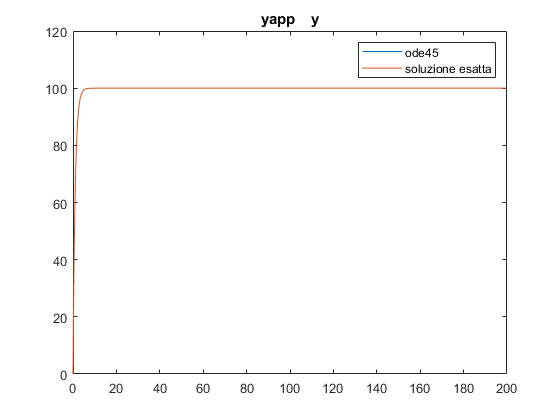


options = odeset('RelTol',1e-6);
[tn,un]=ode45(f,[0 200],0,options);
plot(tn,un)
hold on
fplot(ys,[0 200])
legend('ode45',"soluzione esatta")
title("yapp    y")

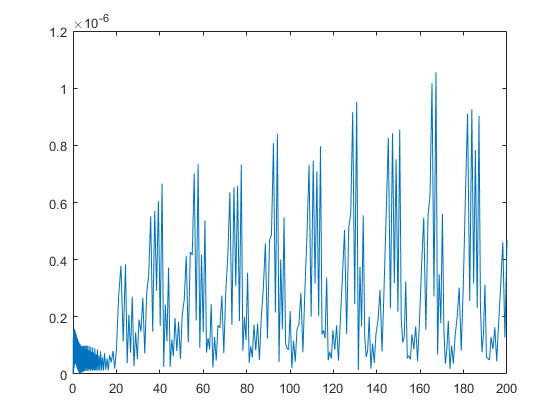

figure
err = abs((ys(tn)-un)./(ys(tn)));
plot(tn,err)

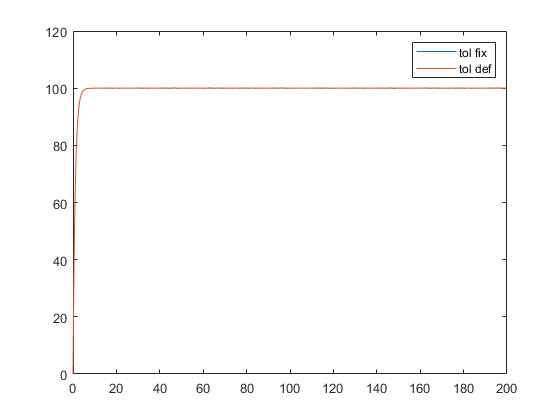


figure
plot(tn,un)
hold on
plot(t,u)
legend("tol fix","tol def")